## **RETO DE DINÁMICA DE SISTEMAS**

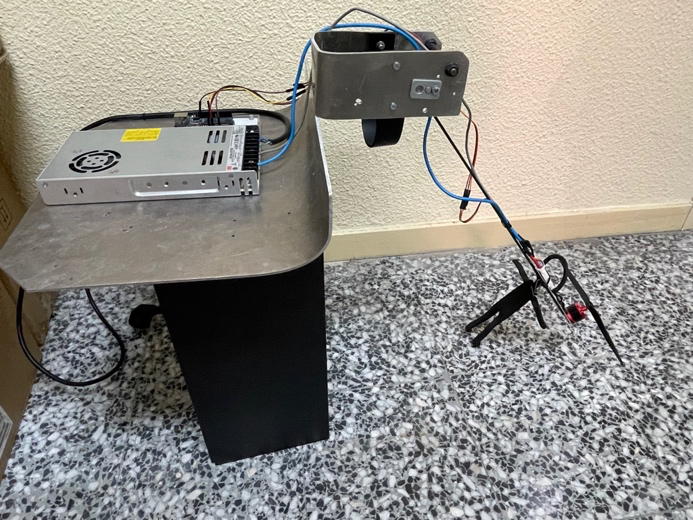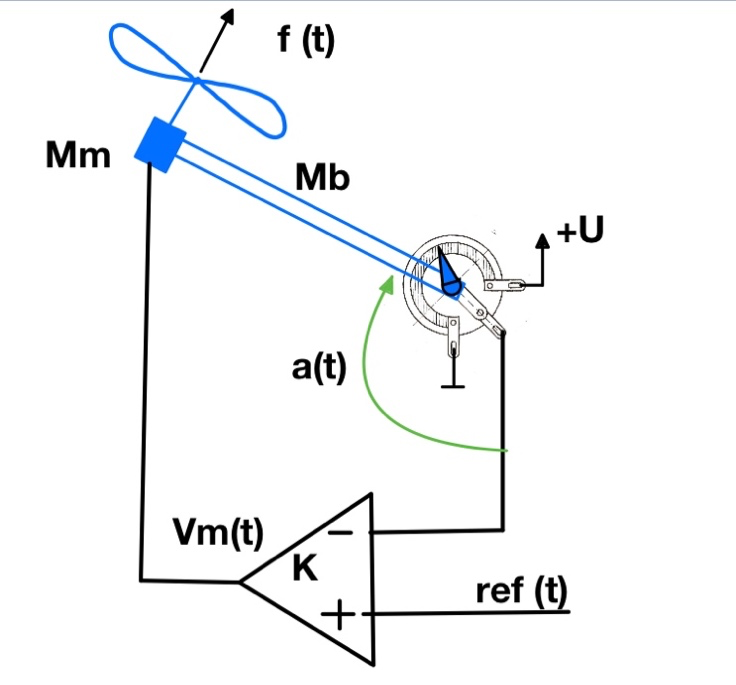

clear all 
close all
s=tf('s');

# Variables no definidas por la solución.

Bm=0.006 %coeficiente de amortiguamiento del motor 

Bm = 0.0060

B=0.006 %coeficiente de amortiguamiento de la barra

B = 0.0060

kD=1.4756e-6 %Par resistente de la hélice 

kD = 1.4756e-06

Mb=0.02 %Masa de la barra

Mb = 0.0200

L1=0.8 %Longitud de la barra

L1 = 0.8000

L2=0.0163e-3 %Inductancia del motor 

L2 = 1.6300e-05

K=1

K = 1

Jm=0.1045e-3 %Inercia del motor 

Jm = 1.0450e-04

# Variables definidas por la solución.


Mmotor=0.054 %Masa del motor

Mmotor = 0.0540

Mpalas=0.022 %Masa de las palas

Mpalas = 0.0220

MR=Mmotor+Mpalas %Masa del rotor

MR = 0.0760

g=9.81 %Aceleración de la gravedad 

g = 9.8100

a=pi/6 %Ángulo de equilibrio

a = 0.5236

R=0.124 %Resistencia del motor

R = 0.1240

KV=920*2*pi/60 %velocidad angular del motor

KV = 96.3422

Kb=1/KV

Kb = 0.0104

Kp=Kb

Kp = 0.0104

KR=2.316082*(10^-5) %Resistencia de la fuerza de empuje

KR = 2.3161e-05


K1=g*L1*cos(a)*((Mb/2)+MR) 

K1 = 0.5845

K2=(L1^2)*((Mb/3)+MR)

K2 = 0.0529

fo=g*sin(a)*((Mb/2)+MR) %fuerza en el equilibrio

fo = 0.4218

wo=sqrt(fo/KR) %velocidad angular en el equilibrio

wo = 134.9559

# Cálculo de la función de transferencia

A=tf(1/(Jm*s+Bm))

A =
 
           1
  -------------------
  0.0001045 s + 0.006
 
Continuous-time transfer function.



C=feedback(A,2*kD*wo) %Primer feedback en la retroalimentación P_R

C =
 
            1
  ----------------------
  0.0001045 s + 0.006398
 
Continuous-time transfer function.




D=tf(1/(KV*(R+L2*s)))

D =
 
          1
  -----------------
  0.00157 s + 11.95
 
Continuous-time transfer function.



F=D*C

F =
 
                   1
  ------------------------------------
  1.641e-07 s^2 + 0.001258 s + 0.07644
 
Continuous-time transfer function.



G=feedback(F,Kb) %Segundo feedback ubicado en u_e

G =
 
                   1
  ------------------------------------
  1.641e-07 s^2 + 0.001258 s + 0.08682
 
Continuous-time transfer function.




H=tf((K*L1*2*KR*wo)/(K2*(s^2)+B*s+K1));
I=G*H;
FT=feedback(I,((2*5)/(3*pi))) %Último feedback A/V_ref

FT =
 
                               0.005001
  -------------------------------------------------------------------
  8.682e-09 s^4 + 6.658e-05 s^3 + 0.004601 s^2 + 0.001256 s + 0.05605
 
Continuous-time transfer function.



**Nota:** Todas la variables están en unidades del SI.

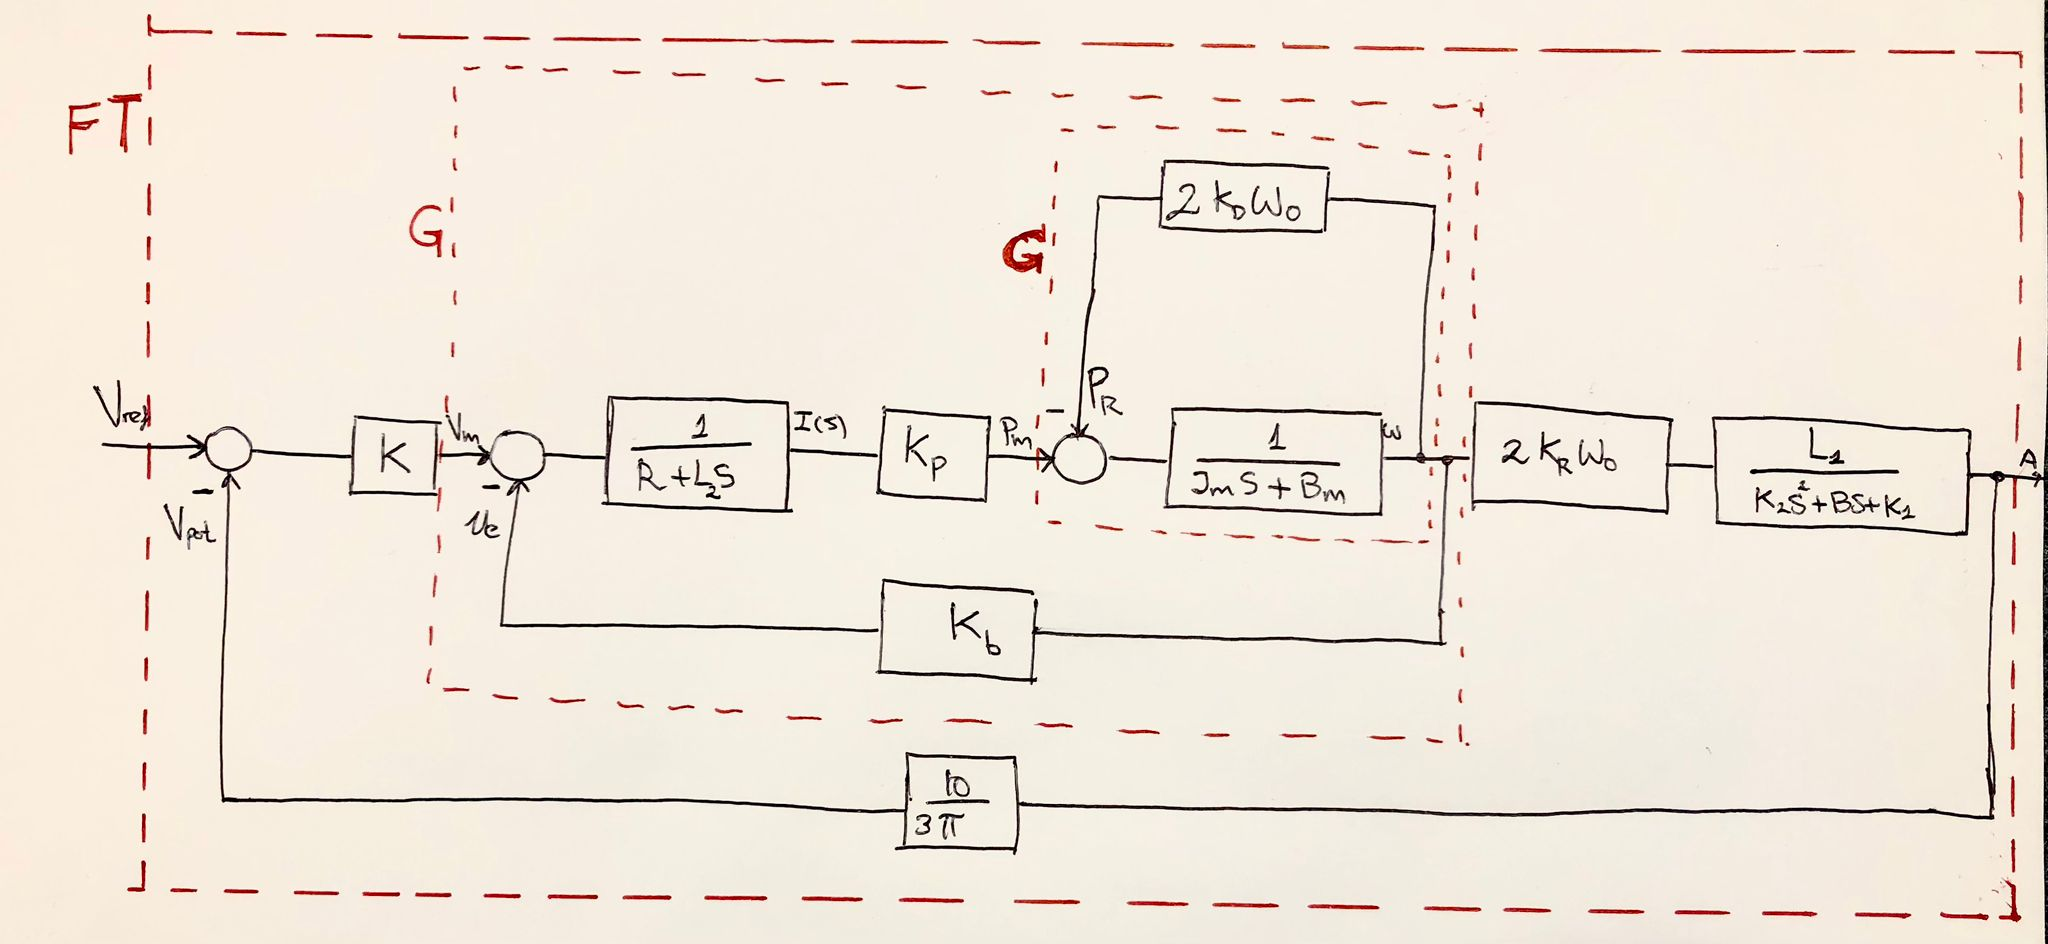

# Simulación de la respuesta ante el escalón

La simulación de la función de transferencia para los valores dados en 120 segundos es la siguiente.

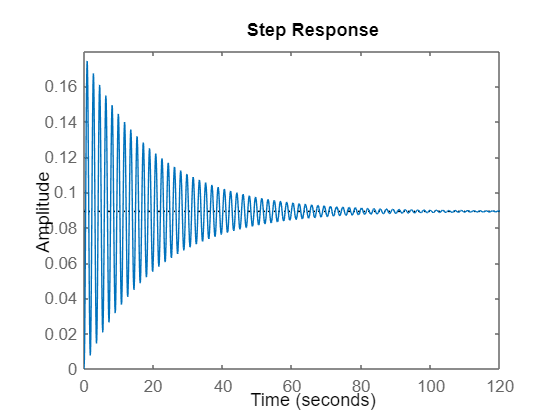

step(FT) %Ensayo de 120 segundos con los datos introducidos

stepinfo(FT)

ans = struct with fields:
         RiseTime: 0.3031
    TransientTime: 80.1482
     SettlingTime: 80.1482
      SettlingMin: 0.0076
      SettlingMax: 0.1744
        Overshoot: 95.5006
       Undershoot: 0
             Peak: 0.1744
         PeakTime: 0.8994


polos = pole(FT)

polos = 1.0e+03 *

  -7.5990 + 0.0000i
  -0.0696 + 0.0000i
  -0.0000 + 0.0035i
  -0.0000 - 0.0035i


# Análisis del sistema y reducción

Para analizar el sistema primero estudiamos sus polos, donde se observa que los dos primeros que ofrece MATLAB son despreciables frente a los dominantes (que son los dos últimos). Podemos reducirlo hasta un sistema de segundo orden. 

%Sistema del modelo que es de cuarto orden
FT= zpk(FT) %Pasamos FT a formato zpk

FT =
 
                  5.7602e+05
  ------------------------------------------
  (s+7599) (s+69.64) (s^2 + 0.09668s + 12.2)
 
Continuous-time zero/pole/gain model.



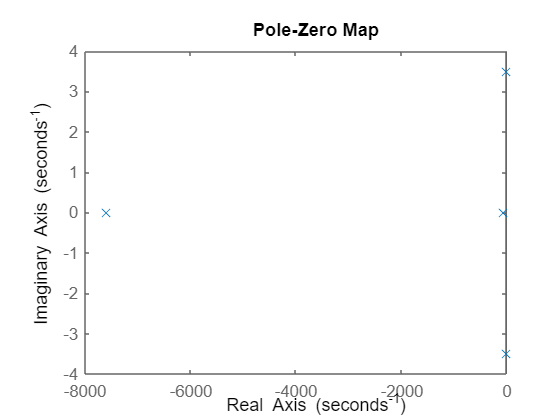

pzmap(FT)


% Sistema reducido a uno de tercer orden
FT3aprox = FT*(s-polos(1,1))/(-real(polos(1,1))) %Obtenemos la función de transferencia equivalente de tercer orden

FT3aprox =
 
               75.802 (s+7599)
  ------------------------------------------
  (s+7599) (s+69.64) (s^2 + 0.09668s + 12.2)
 
Continuous-time zero/pole/gain model.



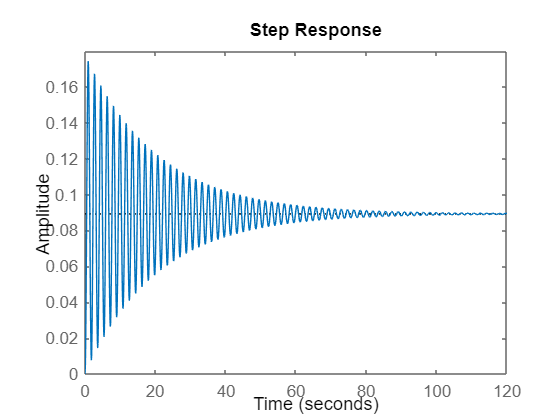

step(FT3aprox) %Ensayo de 120 segundos

stepinfo(FT3aprox)

ans = struct with fields:
         RiseTime: 0.3031
    TransientTime: 80.1482
     SettlingTime: 80.1482
      SettlingMin: 0.0076
      SettlingMax: 0.1744
        Overshoot: 95.5029
       Undershoot: 0
             Peak: 0.1744
         PeakTime: 0.8994



% Sistema reducido a uno de segundo orden
FT2aprox = FT3aprox*(s-polos(2,1))/(-real(polos(2,1))) %Función de transferencia de segundo orden equivalente

FT2aprox =
 
          1.0886 (s+7599) (s+69.64)
  ------------------------------------------
  (s+7599) (s+69.64) (s^2 + 0.09668s + 12.2)
 
Continuous-time zero/pole/gain model.



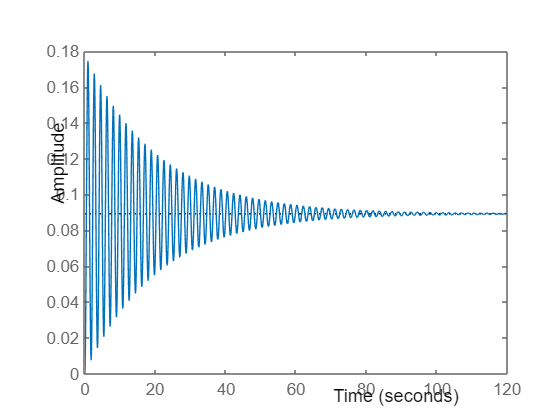

step(FT2aprox)

stepinfo(FT2aprox)

ans = struct with fields:
         RiseTime: 0.3015
    TransientTime: 80.1393
     SettlingTime: 80.1393
      SettlingMin: 0.0074
      SettlingMax: 0.1747
        Overshoot: 95.7449
       Undershoot: 0
             Peak: 0.1747
         PeakTime: 0.8994


Se observa que con respecto a la gráfica de la función de transferencia inicial no hay cambios apreciables debido a que los polos que se le han quitado no eran muy significantes para el sistema. 